# 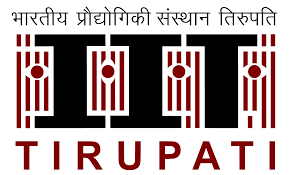            ***LAB SHEET-07***

## *NAME : A NIRANJAN REDDY  *           *ROLL NUMBER : EE23B001*

## **INCREASING SAMPLING RATE USING INTERPOLATOR**

Omega_N = 15; % Maximum limit for frequencies
Tmax = 5;     % Maximum time duration
I = 3;        % Number of cosine terms in the summation
dt = 1/1000;  % Time step for continuous signal

t = 0:dt:Tmax; % Time vector
Omega_i = randi(Omega_N,[1,I]) % random frequencies for each cosine term

Omega_i =     13    14     2


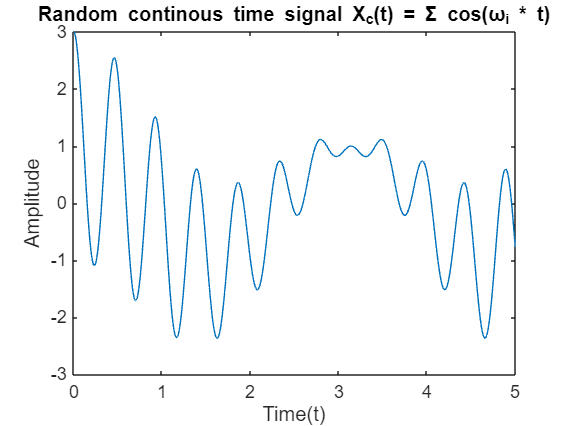


X_c = zeros(size(t)); % Zero matrix of original signal X_c(t) of size t

for i = 1:I
    X_c = X_c + cos(Omega_i(i).*t); % initializing the original signal X_c(t)
end

figure
plot(t,X_c)
xlabel('Time(t)')
ylabel('Amplitude')
title('Random continous time signal X_c(t) = Σ cos(ω_i * t)')

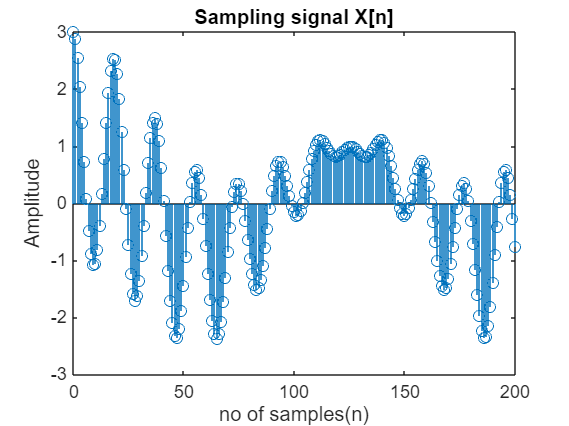


T = 1/40; % T << pi/15
n = 0:floor(Tmax/T); %
X_n = zeros(size(n));  % Initialize signal as zero
for i = 1:I 
    X_n = X_n + cos(Omega_i(i) * n * T);  % Accumulate cosine terms
end

figure
stem(n,X_n)
xlabel('no of samples(n)')
ylabel('Amplitude') 
title('Sampling signal X[n]')


L = 3;
n2 = 0:floor(Tmax/T)*L; 
X_e = zeros(size(n2)); % zero matrix of expanded signal of sampled signal x[n]

for i = 1:length(n2)
    if mod(i-1, L) == 0
        X_e(i) = X_n(((i-1)/L)+1);  % Compute x( n / L) for n = 0, L, 2L, ...
    else
        X_e(i) = 0;         % Set x_e[n] to 0 for other values
    end
end

X_e

X_e =     3.0000         0         0    2.8858         0         0    2.5559         0         0    2.0475         0         0    1.4175         0         0    0.7365         0         0    0.0803         0         0   -0.4783         0         0   -0.8781         0         0   -1.0762         0         0   -1.0530         0         0   -0.8144         0         0   -0.3909         0         0    0.1661         0         0    0.7897         0         0    1.4057         0         0    1.9408         0


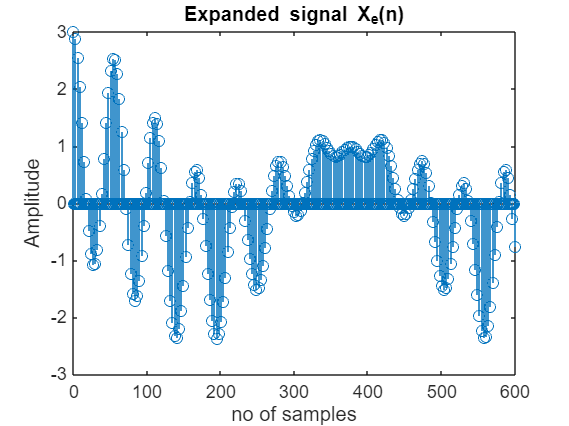


figure
stem(n2,X_e)
xlabel('no of samples')
ylabel('Amplitude') 
title('Expanded signal X_e(n)')

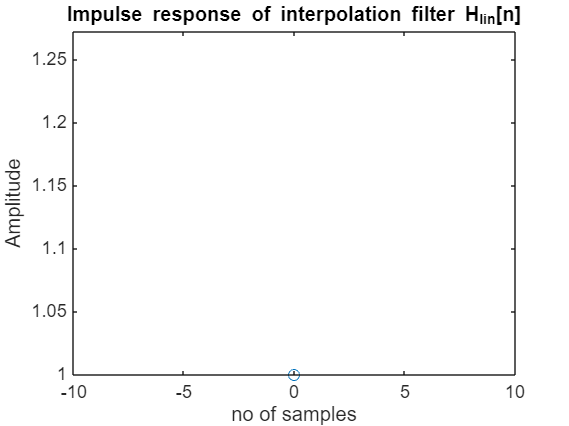

%impulse response of a linear interpolation signal
n1 = -7:1:7;
H_lin = zeros(size(n1));

for i = 1:length(n1)
    if (abs(n1(i))<L)
        H_lin(i) = 1 - (abs(n1(i))/L); 
    else
        H_lin(i) = 0;
    end
end

figure
stem(n1,H_lin)
xlabel('no of samples')
ylabel('Amplitude') 
title('Impulse response of interpolation filter H_l_i_n[n]')

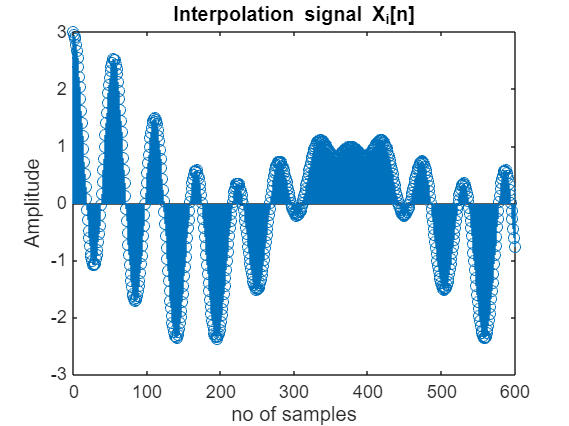

X_i = conv(X_e,H_lin,'same'); % linear interpolation signal of Xe[n] is Xi[n]

figure
stem(n2,X_i)
xlabel('no of samples')
ylabel('Amplitude') 
title('Interpolation signal X_i[n]')

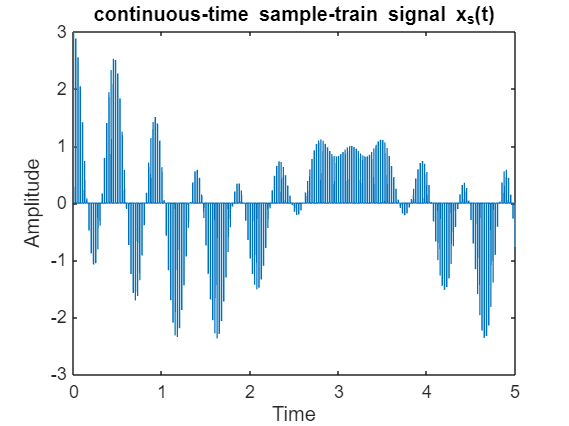

% continous time sample trian signal

n_1 = 0 : T/L : (length(X_i)-1)*T/L; 
X_s = zeros(1,length(t));
for i = 1:length(n2)
 X_s = X_s + X_i(i)*((abs(t- n_1(i))) < 1e-12 );
end

figure;
plot(t, X_s);
title('continuous-time sample-train signal x_s(t)');
xlabel('Time');
ylabel('Amplitude');

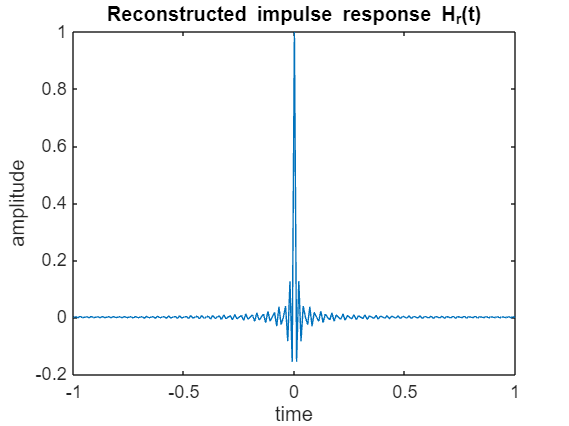

% reconstruction filter using the formula from Appendix
t_f = -1:0.01:1;  % Time range for filter
h_rt = (sin((pi *L.*t_f) / T)) ./ ((pi *L.*t_f) / T);  % impulse response of the reconstruction filter
h_rt(t_f == 0) = 1; % Handle singularity at t = 0

figure
plot(t_f,h_rt)
xlabel('time')
ylabel('amplitude')
title('Reconstructed impulse response H_r(t)')

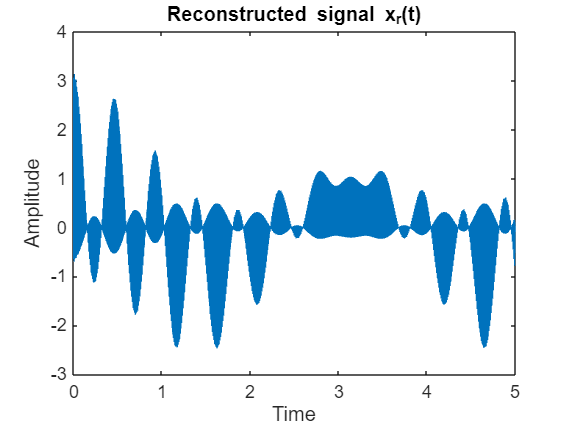

% reconsructed signal 
M = 4;  % dt = Ts/M ==> M = Ts/dt = 100/6 = 16.666 so, approx M = 17
x_bar = zeros(1, length(X_i) * M);  % Create zero padded array of length n_Ts*M
x_bar(1:M:end) = X_i;  % pass the sampled values in padded array

x_rk = conv(x_bar, h_rt, 'same');  % Reconstructed signal

t_rk = linspace(0, Tmax, length(x_rk));  % time interval for signal x_r_k

figure;
plot(t_rk, x_rk);
title('Reconstructed signal x_r(t)');
xlabel('Time');
ylabel('Amplitude');

## Comparing original signal and Reconstructed signal

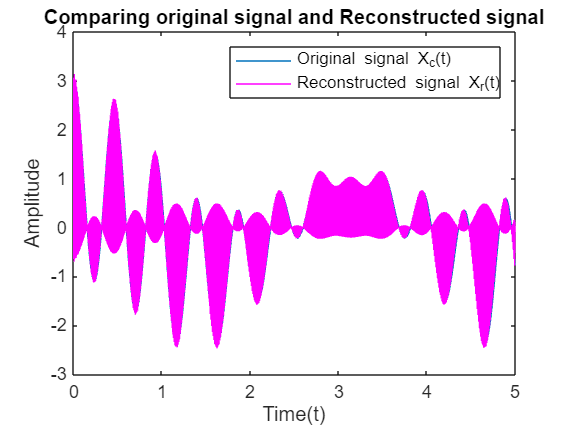

figure
plot(t,X_c)
hold on
plot(t_rk, x_rk,'Color','m');
xlabel('Time(t)')
ylabel('Amplitude')
title('Comparing original signal and Reconstructed signal')
legend('Original signal X_c(t)','Reconstructed signal X_r(t)')

#### USING CUBIC INTERPOLATION FILTER:

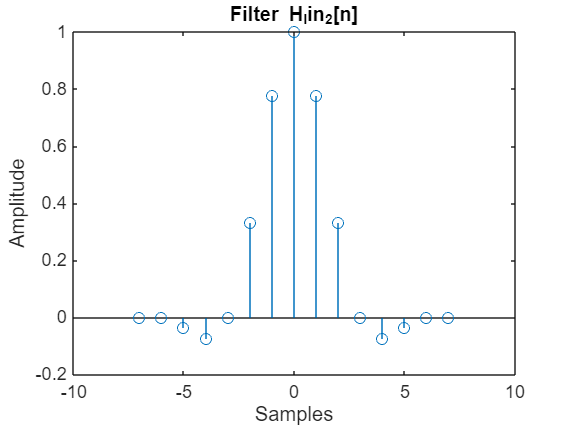

a = -0.5;
H_lin_2 = zeros(1,length(n1));
for i = 1:length(n1)
    if (abs(n1(i))<L )
        H_lin_2(i) = ((a+2)*(abs(n1(i)/L)^3)) - ((a+3)*(abs(n1(i)/L)^2)) + 1;
    elseif (abs(n1(i))>=L) && (abs(n1(i))< 2*L)
        H_lin_2(i) = (a*(abs(n1(i)/L)^3)) - (5*a*(abs(n1(i)/L)^2)) + (8*a*abs(n1(i)/L)) - 4*a;
    else
        H_lin_2(i) = 0;
    end 
end

figure;
stem(n1, H_lin_2);
title('Filter H_lin_2[n]');
xlabel('Samples');
ylabel('Amplitude');

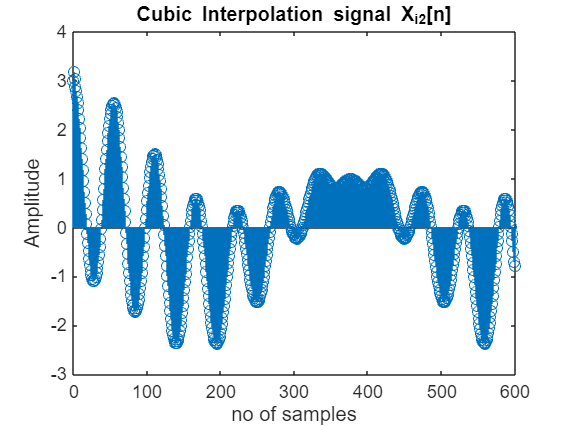

X_i_2 = conv(X_e,H_lin_2,'same'); % Cubic interpolation signal of Xe[n] is Xi[n]

figure
stem(n2,X_i_2)
xlabel('no of samples')
ylabel('Amplitude') 
title('Cubic Interpolation signal X_i_2[n]')

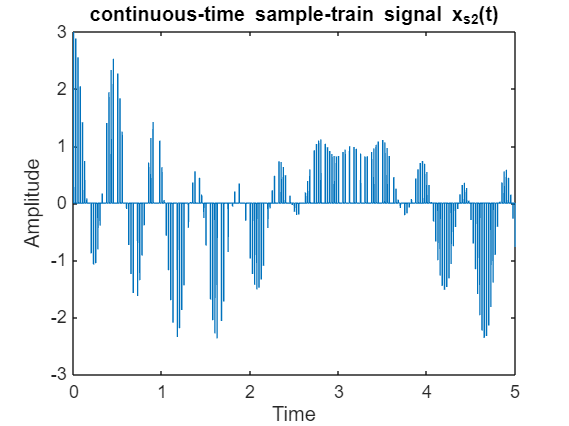

% continous time sample trian signal

n_1 = 0 : T/L : (length(X_i_2)-1)*T/L; 
X_s_2 = zeros(1,length(t));
for i = 1:length(n2)
 X_s_2 = X_s_2 + X_i_2(i)*(t == n_1(i));
end

figure;
plot(t, X_s_2);
title('continuous-time sample-train signal x_s_2(t)');
xlabel('Time');
ylabel('Amplitude');

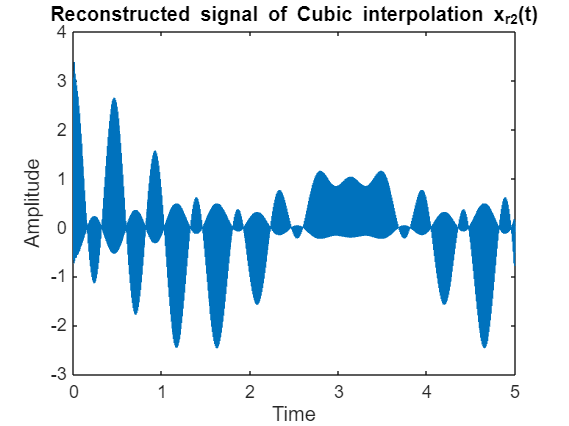

M = 4;  % dt = Ts/M ==> M = Ts/dt = 100/6 = 16.666 so, approx M = 17
x_bar_2 = zeros(1, length(X_i_2) * M);  % Create zero padded array of length n_Ts*M
x_bar_2(1:M:end) = X_i_2;  % pass the sampled values in padded array

x_rk_2 = conv(x_bar_2, h_rt, 'same');  % Reconstructed signal

t_rk_2 = linspace(0, Tmax, length(x_rk_2));  % time interval for signal x_r_k

figure;
plot(t_rk_2, x_rk_2);
title('Reconstructed signal of Cubic interpolation x_r_2(t)');
xlabel('Time');
ylabel('Amplitude');

## Comparing original signal and Reconstructed signal of Cubic interpolation

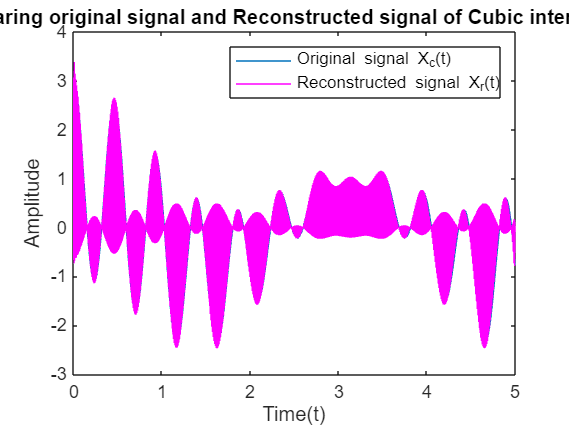

figure
plot(t,X_c)
hold on
plot(t_rk_2, x_rk_2,'Color','m');
xlabel('Time(t)')
ylabel('Amplitude')
title('Comparing original signal and Reconstructed signal of Cubic interpolation')
legend('Original signal X_c(t)','Reconstructed signal X_r(t)')

## Observation:

- By analyzing the outputs of reconstructed signals using linear and cubic interpolators and comparing them with the original signal, it is evident that the cubic interpolator effectively retraces the original signal. 

- The output obtained with the cubic interpolator closely resembles the original signal, while the linear interpolator produces a less accurate reconstruction. Therefore, for our input signal, the cubic interpolator proves to be more efficient.